clc;clear;close all 


% single integrator collision avoidance demo 
time_vec = linspace(0,5,100);
dt = time_vec(2) - time_vec(1); 

% preallocations
pos  = zeros(2,length(time_vec)); % system states
vel  = zeros(2,length(time_vec)); % system input 

% assumes that the mass has following initial position in xy, and zero vel
pos(:,1) = [0;0]; 
vel(:,1) = [0;0];

% target position
pos_des = [2;2.5];

% obstacle location
pos_obs = [1;1];
R_obs = 0.3; % m 

% gamma
gamma = 1;  % changing this will make change the safety of the CBF algorithm 

% feedback gain
K = 2.5;

## computation loop


for i = 2:length(time_vec)

    % state 
    pos_curr = pos(:,i-1);
    
    % compute desired velocity through feedback
    pos_error = pos_des - pos_curr; 
    u_des = K*(pos_error);

    % apply CBF filter to compute safe vel. input 
    % u_safe = u_des;
    u_safe = CBF_singleIntegrator(gamma,u_des,pos_curr,pos_obs,R_obs);
    vel(:,i) = u_safe;

    % advance kinematics -> using the safe vel. input
    pos(:,i) = pos_curr + u_safe*dt;
    
end 

u_safe =     5.0000
    6.2500


u_safe =     4.3687
    5.4609


u_safe =     3.8171
    4.7714


u_safe =     3.3351
    4.1689


u_safe =     2.9140
    3.6425


u_safe =     2.5461
    3.1826


u_safe =     2.2246
    2.7808


u_safe =     1.9437
    2.4297


u_safe =     1.6983
    2.1229


u_safe =     1.4839
    1.8548


u_safe =     1.2965
    1.6206


u_safe =     1.1328
    1.4160


u_safe =     0.9898
    1.2372


u_safe =     0.8648
    1.0810


u_safe =     0.7556
    0.9445


u_safe =     0.6602
    0.8253


u_safe =     0.5769
    0.7211


u_safe =     0.5040
    0.6300


u_safe =     0.4404
    0.5505


u_safe =     0.3848
    0.4810


u_safe =     0.3362
    0.4202


u_safe =     0.2937
    0.3672


u_safe =     0.2567
    0.3208


u_safe =     0.2242
    0.2803


u_safe =     0.1959
    0.2449


u_safe =     0.1712
    0.2140


u_safe =     0.1496
    0.1870


u_safe =     0.1307
    0.1634


u_safe =     0.1142
    0.1427


u_safe =     0.0998
    0.1247


u_safe =     0.0872
    0.1090


u_safe =     0.0762
    0.0952


u_safe =     0.0666
    0.0832


u_safe =     0.0581
    0.0727


u_safe =     0.0508
    0.0635


u_safe =     0.0444
    0.0555


u_safe =     0.0388
    0.0485


u_safe =     0.0339
    0.0424


u_safe =     0.0296
    0.0370


u_safe =     0.0259
    0.0323


u_safe =     0.0226
    0.0283


u_safe =     0.0198
    0.0247


u_safe =     0.0173
    0.0216


u_safe =     0.0151
    0.0188


u_safe =     0.0132
    0.0165


u_safe =     0.0115
    0.0144


u_safe =     0.0101
    0.0126


u_safe =     0.0088
    0.0110


u_safe =     0.0077
    0.0096


u_safe =     0.0067
    0.0084


u_safe = 2×1
    0.0059
    0.0073


u_safe = 2×1
    0.0051
    0.0064


u_safe = 2×1
    0.0045
    0.0056


u_safe = 2×1
    0.0039
    0.0049


u_safe = 2×1
    0.0034
    0.0043


u_safe = 2×1
    0.0030
    0.0037


u_safe = 2×1
    0.0026
    0.0033


u_safe = 2×1
    0.0023
    0.0028


u_safe = 2×1
    0.0020
    0.0025


u_safe = 2×1
    0.0017
    0.0022


u_safe = 2×1
    0.0015
    0.0019


u_safe = 2×1
    0.0013
    0.0017


u_safe = 2×1
    0.0012
    0.0015


u_safe = 2×1
    0.0010
    0.0013


u_safe = 2×1
    0.0009
    0.0011


u_safe = 2×1
1.0e-03 *

    0.7740
    0.9675


u_safe = 2×1
1.0e-03 *

    0.6763
    0.8453


u_safe = 2×1
1.0e-03 *

    0.5909
    0.7386


u_safe = 2×1
1.0e-03 *

    0.5163
    0.6453


u_safe = 2×1
1.0e-03 *

    0.4511
    0.5638


u_safe = 2×1
1.0e-03 *

    0.3941
    0.4927


u_safe = 2×1
1.0e-03 *

    0.3444
    0.4305


u_safe = 2×1
1.0e-03 *

    0.3009
    0.3761


u_safe = 2×1
1.0e-03 *

    0.2629
    0.3286


u_safe = 2×1
1.0e-03 *

    0.2297
    0.2871


u_safe = 2×1
1.0e-03 *

    0.2007
    0.2509


u_safe = 2×1
1.0e-03 *

    0.1754
    0.2192


u_safe = 2×1
1.0e-03 *

    0.1532
    0.1915


u_safe = 2×1
1.0e-03 *

    0.1339
    0.1673


u_safe = 2×1
1.0e-03 *

    0.1170
    0.1462


u_safe = 2×1
1.0e-03 *

    0.1022
    0.1277


u_safe = 2×1
1.0e-03 *

    0.0893
    0.1116


u_safe = 2×1
1.0e-04 *

    0.7802
    0.9752


u_safe = 2×1
1.0e-04 *

    0.6817
    0.8521


u_safe = 2×1
1.0e-04 *

    0.5956
    0.7445


u_safe = 2×1
1.0e-04 *

    0.5204
    0.6505


u_safe = 2×1
1.0e-04 *

    0.4547
    0.5684


u_safe = 2×1
1.0e-04 *

    0.3973
    0.4966


u_safe = 2×1
1.0e-04 *

    0.3471
    0.4339


u_safe = 2×1
1.0e-04 *

    0.3033
    0.3791


u_safe = 2×1
1.0e-04 *

    0.2650
    0.3313


u_safe = 2×1
1.0e-04 *

    0.2315
    0.2894


u_safe = 2×1
1.0e-04 *

    0.2023
    0.2529


u_safe = 2×1
1.0e-04 *

    0.1768
    0.2210


u_safe = 2×1
1.0e-04 *

    0.1544
    0.1931


u_safe = 2×1
1.0e-04 *

    0.1349
    0.1687


u_safe = 2×1
1.0e-04 *

    0.1179
    0.1474


u_safe = 2×1
1.0e-04 *

    0.1030
    0.1288


u_safe = 2×1
1.0e-04 *

    0.0900
    0.1125


## visualization loop

f = figure;
plot(pos(1),pos(2),'b.','MarkerSize', 48);
hold on
plot(pos_des(1),pos_des(2),'gx','MarkerSize', 12,'LineWidth',3)
viscircles(pos_obs',R_obs,'Color','r')

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


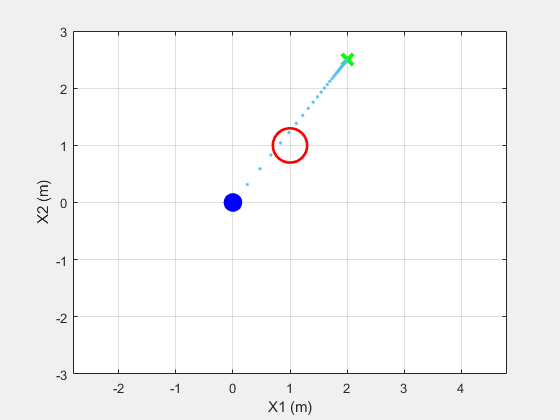

axis([-3 3 -3 3]);
grid on 
axis equal
xlabel('X1 (m)')
ylabel('X2 (m)')

waitforbuttonpress % press any button on the keyboard to resume

for i = 2:length(time_vec)
    plot(pos(1,i),pos(2,i),'.','Color',[0.3010 0.7450 0.9330]);
    drawnow
    pause(0.01)
end 

## CBF

% CBF for single integrator example -> Eqns (7) and (8)
function u_safe = CBF_singleIntegrator(gamma,u_des,pos_curr,pos_obs,R_obs)
    h = CBF_ballObs(pos_curr,pos_obs,R_obs);
    b = gamma*h;
    A = -2*(pos_curr - pos_obs)';
    H = 2*eye(2); f = -2*u_des;
    lb = -1*ones(2,1); ub = ones(2,1);
    Aeq = []; beq = []; uguess = [0;0];
    options = optimoptions('quadprog','Algorithm','active-set','Display','none');
    u_safe = quadprog(H,f,A,b,Aeq,beq,lb,ub,uguess,options);
end 

function h = CBF_ballObs(pos_curr,pos_obs,R_obs)
    h = norm(pos_curr - pos_obs)^2 - R_obs^2;
end 
